Load the data and find the SVD.

Faces = load("yalefaces.mat");
Faces = Faces.X;
[U,D,V]=svd(Faces);

View a few faces in the database.

face = 1
imagesc(flip(rot90(reshape(Faces(:,face),32,32))))

Next we view the first few (up to 10) left singular vectors as images, these are the eigenfaces. Perhaps you can see some aspects of faces represented by each.

n =6;

n = 6

DD = diag(D).^2;
p = sum(DD(1:n))/sum(DD);
text = sprintf('%.2f%% of the information in the faces \n is in the first %i eigenvextors.', [p*100, n]);
display(text);

text =     '93.89% of the information in the faces 
      is in the first 6 eigenvextors.'


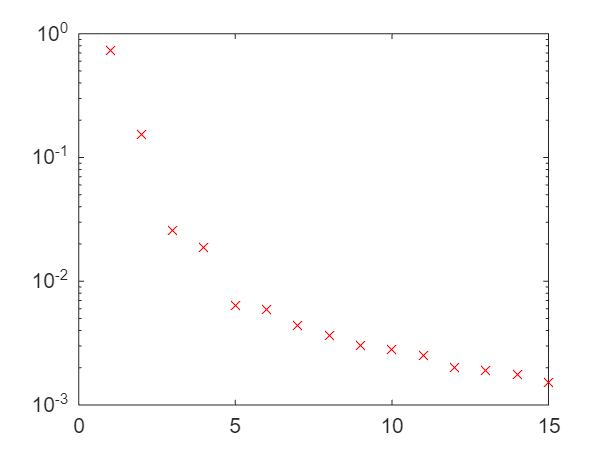

clf('reset')
semilogy(DD(1:15)./sum(DD),'xr')

The next section dispays the n top singularvectors.

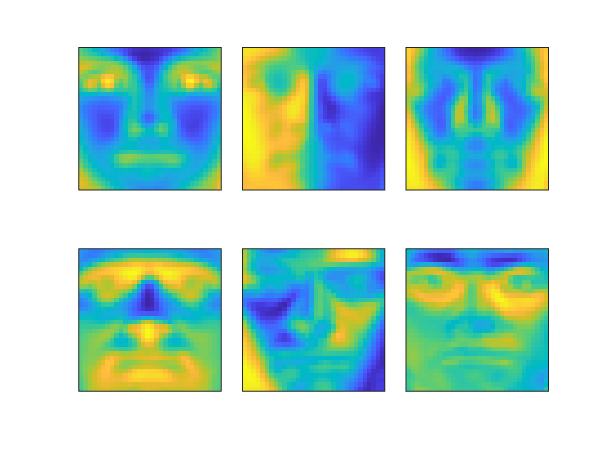

clf('reset')
tiledlayout('flow','TileSpacing','Compact')
for i = 1:n
    %m = ceil(n/sqrt(n));
    %subplot(m, m, i)
    nexttile
    imagesc(flip(rot90(reshape(U(:,i),32,32))))
    daspect([1 1 1])
    %set(gca, 'PlotBoxAspectRatio', [1,1,1],'XTick',[],'YTick',[])
    set(gca, 'XTick', [], 'YTick', [])
end